clear;
%Start with selecting the image
img = "BA PTPP glass film_200 micron thick.jpg";
%imshow("ESF and LSF.jpg"); %If totally new image needs to be cropped

%Select area from image for calculation of the ESF

I=imread(img);
% imshow(I);
x =2500

x = 2500

y = 200

y = 200

w = 1500

w = 1500

h = 1500

h = 1500

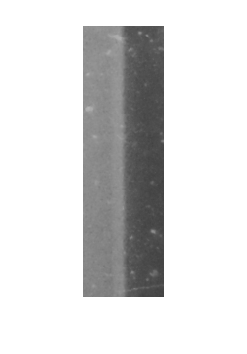

rect = [x y w h];
I_cropped = imcrop(I,rect) ;
% imshow(I_cropped);

%Now rotate convert ROI to gray and rotate untill slanted edge and image
%edge are paralell, afterwards show area again

I_cropped=imrotate(I_cropped,-89.25);
GI_cropped = rgb2gray(I_cropped); 
% imshow(GI_cropped);
ROI =  GI_cropped(175:445, 1055:1135);            %Select the final ROI
imshow(ROI);

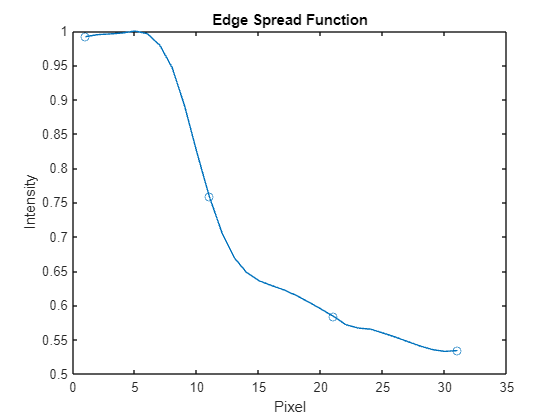


% ESF: Average Intensity over all rows, plot it 

figure;
ESF = mean(ROI);
selESF = ESF(33:63);         %Start with the whole ROI and then select wanted edge values
% selESF = selESF(300:400);
l_selESf= 1:length(selESF);
selESF = selESF/max(selESF);
% selESF(1:5) = 1;
% selESF(17:31) = 0.624121;

figure;
plot(l_selESf,selESF, '-o','MarkerIndices',1:10:length(selESF));
title('Edge Spread Function')
xlabel('Pixel')
ylabel('Intensity')


% Fermi Fit : Fit parameters of the fermi Dirac Function to the image data

fdfit = @(x)x(1)./(exp((l_selESf-x(2))./x(3))+1)+x(4)-selESF;
x0 = [0.438092,11,2000,0.604]

x0 = 1.0e+03 *

    0.0004    0.0110    2.0000    0.0006


x = lsqnonlin(fdfit,x0);


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


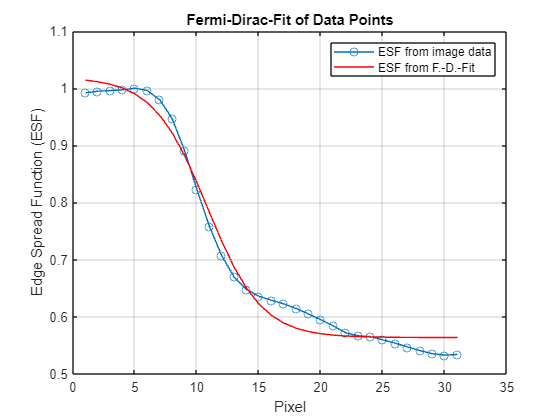


figure;
plot(l_selESf,selESF,'-o',l_selESf,fdfit(x)+selESF,'-r');
title('Fermi-Dirac-Fit of Data Points')
ylabel('Edge Spread Function (ESF)')
xlabel('Pixel')
legend('ESF from image data','ESF from F.-D.-Fit')
grid on

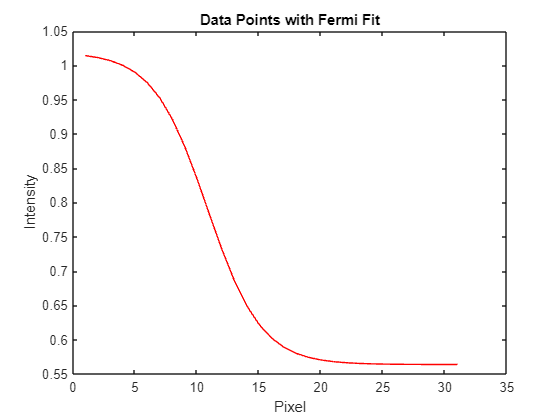


figure;
plot(l_selESf,fdfit(x)+selESF,'-r');
title('Data Points with Fermi Fit')
ylabel('Intensity')
xlabel('Pixel')

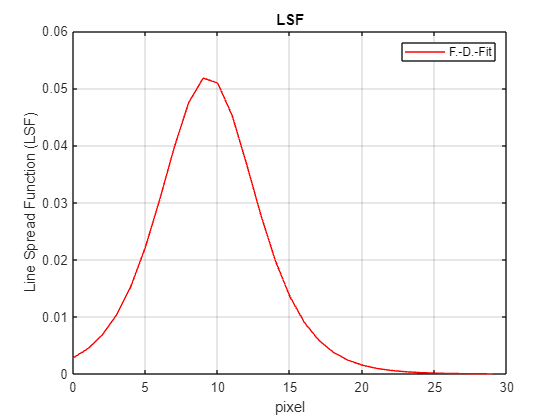



% LSF: Deriviate both ESFs and plot them against eachother

selLSF= abs(diff(selESF));          % LSF from the ESF data
fun2 = fdfit(x)+selESF;     
fdfitLSF =abs(diff(fun2));        %LSF of the fitted Fermi-Dirac-ESF
e = 0:length(selLSF)-1;


plot(e,fdfitLSF,'-r');
title('LSF')
xlabel('pixel')
ylabel('Line Spread Function (LSF)')
legend('F.-D.-Fit')
grid on

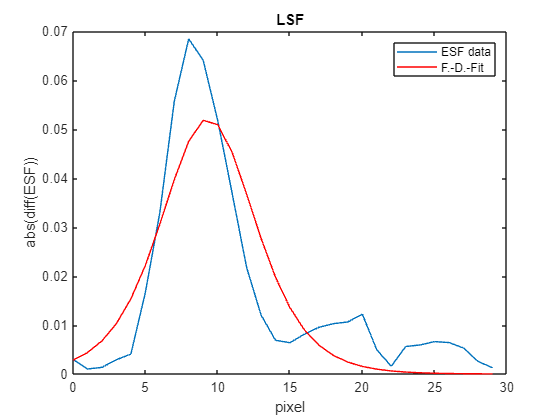


figure;                      %plot the two curves
plot(e,selLSF,e,fdfitLSF,'-r');
title('LSF')
xlabel('pixel')
ylabel('abs(diff(ESF))')
legend('ESF data','F.-D.-Fit')

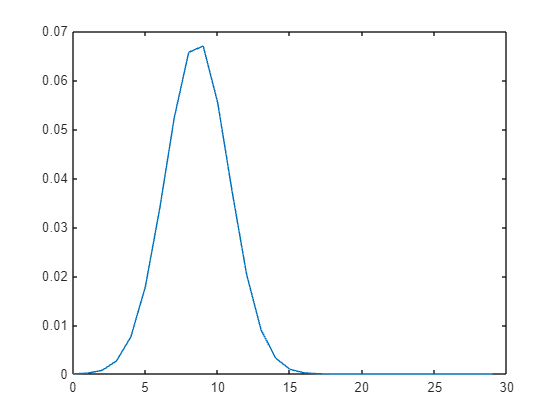


%Gaussian Fit for LSF Data; get the parameters from the Curve Fitting Option

a1 = 0.0681;
b1 = 8.5916;
c1 = 3.1000;

gfLSF = a1.*exp(-((e-b1)./c1).^2);
plot(e,gfLSF);

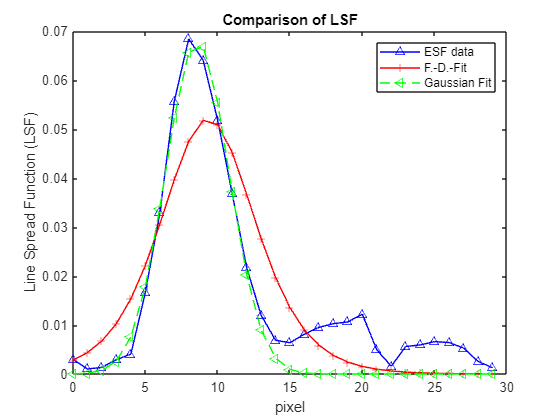


% Now Lets also compare all 3 plots in one

plot(e,selLSF,'^ -b',e,fdfitLSF,' -+r',e,gfLSF,'< --g');
title('Comparison of LSF')
xlabel('pixel')
ylabel('Line Spread Function (LSF)')
legend('ESF data','F.-D.-Fit','Gaussian Fit')

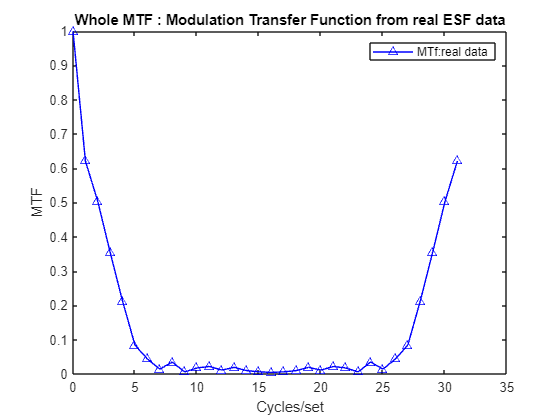


%Aplication of a Hanning Window 

% % Length of the LSF
% N = length(e);
% 
% % Generate a 1D Hanning window of the same length as the LSF
% window = hann(N);
% 
% % Apply the Hanning window to the LSF
% windowed_lsf = lsf .* window;
% 
% % Plot the original and windowed LSF
% figure;
% subplot(2, 1, 1);
% plot(lsf);
% title('Original LSF');
% 
% subplot(2, 1, 2);
% plot(windowed_lsf);
% title('Windowed LSF');




%%    MODULATION TRANSFER FUNCTION (MTF)



%Calculate the MTF by calcualting the Discrete Fourier Transform of the LSF

figure ;

L = length(selLSF);          %First for the real LSF data
n = 2^nextpow2(L);



selMTF =abs(fft(selLSF,n));         %
selMTF = selMTF/max(selMTF);
sel_selMTF = selMTF(1:(length(selMTF)/2));         %Only interest in real Parts of the LSF  
wl_selMTF = 0:length(selMTF)-1;
hl_selMTF = 0:length(sel_selMTF)-1;


%Now Plot the data we receive for a first check. Due to the Fourier
%transform the result will include a real part and an imaginary part. This
%can be seen in the symmetry of the result

plot(wl_selMTF,selMTF,'^ -b');                      %Plotting ESF data
title('Whole MTF : Modulation Transfer Function from real ESF data')
ylabel('MTF')
xlabel('Cycles/set')
legend('MTf:real data')

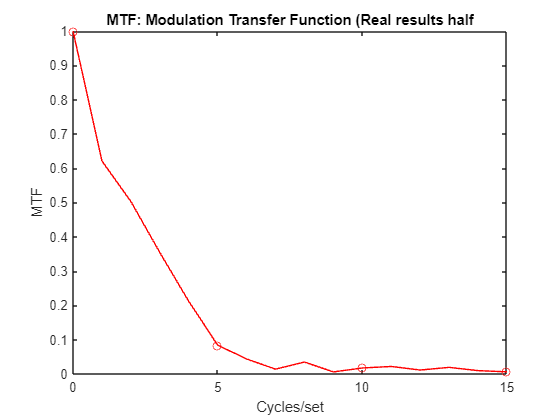


% Now plot only one half as we only need real results


plot(hl_selMTF,sel_selMTF,'-o r','MarkerIndices',1:5:length(sel_selMTF));
title('MTF: Modulation Transfer Function (Real results half')
ylabel('MTF')
xlabel('Cycles/set')

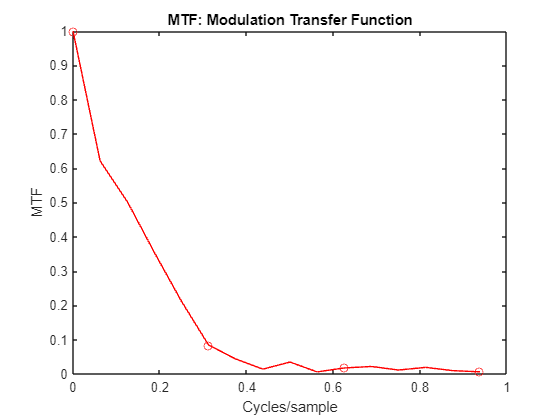


%We will now convert the frequency axis into different units as Matlab only
%knows the steps in naturel numbers, but these are not the frequency
%results of the DFT.

%CYCLES PER SAMPLE

%Conversion to Cycles/sample, should show a fequency axis going from zero
%to one.Cycles are the amount of times, the DFT "cycles" through the set,
%which is a result of the DFT. Samples means the number of datapoints,
%which where used by the DFT.


set = 1/(length(hl_selMTF));

figure;
plot(hl_selMTF*set,sel_selMTF,'-o r','MarkerIndices',1:5:length(sel_selMTF));
title('MTF: Modulation Transfer Function')
ylabel('MTF')
xlabel('Cycles/sample')


%LINEPAIRS PER MM

%Assuming we have one pixel per sample this is also the result in
%Cycles/pixel
%now as the last step, calculate the result in Lp/mm. We assume One cycle =
%one lp, and also one pixel = pixelpitch[mm]

pp = (9.6*10^(-3)) %pixelpitch in mm

pp = 0.0096

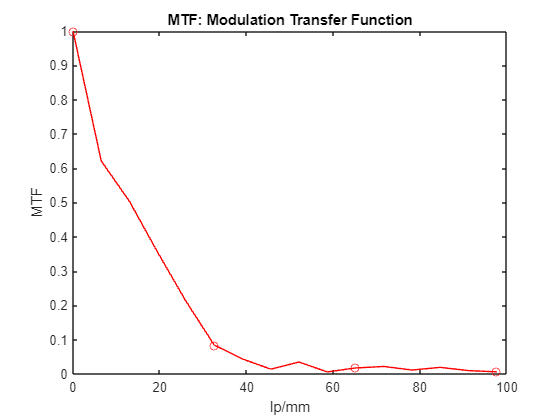

set = set*(1/pp);

figure;
plot(hl_selMTF*set,sel_selMTF,'-o r','MarkerIndices',1:5:length(sel_selMTF));
title('MTF: Modulation Transfer Function')
ylabel('MTF')
xlabel('lp/mm')

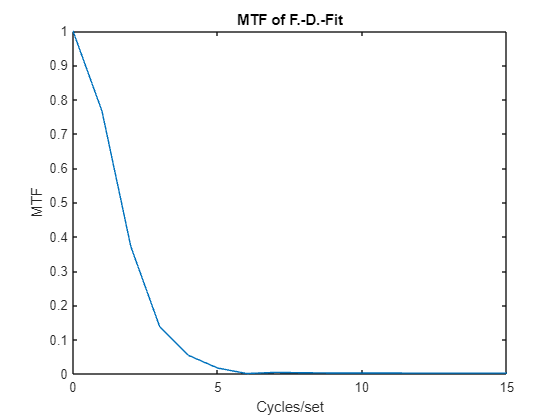



%COMPARISON

%Now, as next test, we calcualte the MTF for the F.-D.-Fit, to compare the
%results.

figure;

L2 = length(fdfitLSF);         %Now the fitted Fermi-Dirac-LSF data
n = 2^nextpow2(L2);

fdfit_MTF =abs(fft(fdfitLSF,n));         %FT of the LSF
fdfit_MTF = fdfit_MTF/max(fdfit_MTF);    %Norm
hl_fdfitMTF = fdfit_MTF(1:length(fdfit_MTF)/2);  %Again only interested in the real results 
h = 0: length(hl_fdfitMTF)-1;


plot(h,hl_fdfitMTF);
title('MTF of F.-D.-Fit')
xlabel('Cycles/set')
ylabel('MTF')

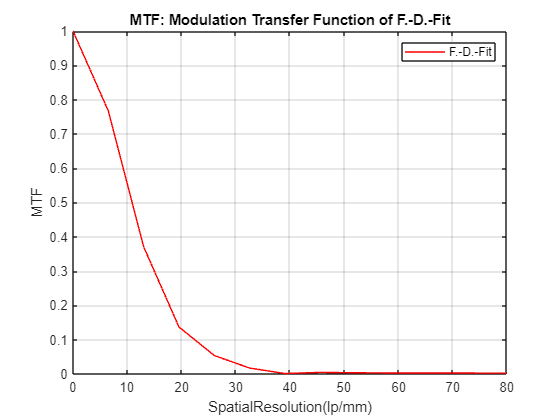


%Conversion to lp/mm
fdfitset = 1/(length(hl_fdfitMTF));
psize = 0.0096; % size of pixels in mm
fdfitset = fdfitset*(1/psize);
plot(h*fdfitset,hl_fdfitMTF,'-r');
title('MTF: Modulation Transfer Function of F.-D.-Fit')
xlabel('SpatialResolution(lp/mm)')
ylabel('MTF')
legend('F.-D.-Fit ')
grid on
axis([0 80 0 1]);

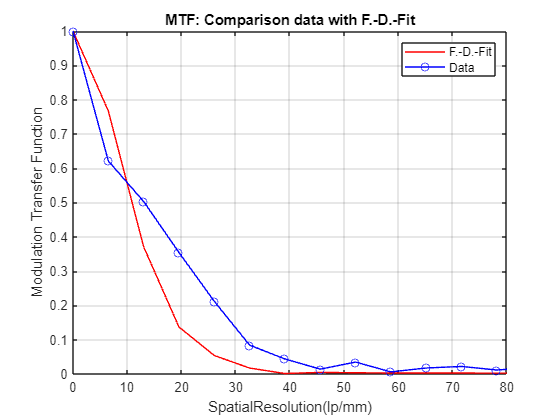





%Comparison 

plot(h*fdfitset,hl_fdfitMTF,'-r',h*fdfitset,sel_selMTF,'-o b');
title('MTF: Comparison data with F.-D.-Fit')
xlabel('SpatialResolution(lp/mm)')
ylabel('Modulation Transfer Function')
legend('F.-D.-Fit','Data')
grid on
axis([0 80 0 1]);


%%%%% Now the same for the Gaussian Fit


figure;

L2 = length(gfLSF);         %Now the fitted Fermi-Dirac-LSF data
n = 2^nextpow2(L2);

gffit_MTF =abs(fft(gfLSF,n));         %
gffit_MTF = gffit_MTF/max(gffit_MTF);    %Norm
hl_gffitMTF = gffit_MTF(1:length(gffit_MTF)/2);
h_gffitMTF =0:length(hl_gffitMTF)-1;

psize = 0.0096                     % size of pixels in mm

psize = 0.0096

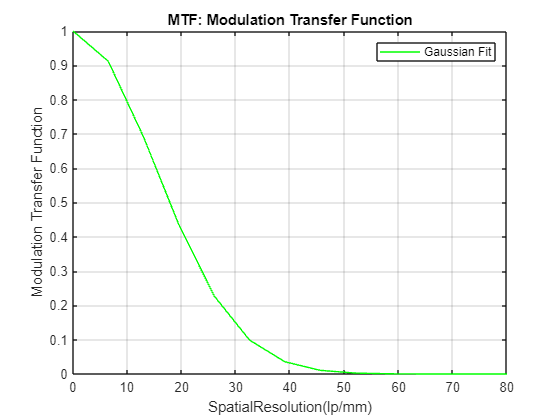

sf = 1./(length(hl_gffitMTF)*psize);     %Sampling Frequency

%Now plot the result

plot(sf*h_gffitMTF,hl_gffitMTF,'-g');
title('MTF: Modulation Transfer Function')
xlabel('SpatialResolution(lp/mm)')
ylabel('Modulation Transfer Function')
legend('Gaussian Fit')
grid on
axis([0 80 0 1]);

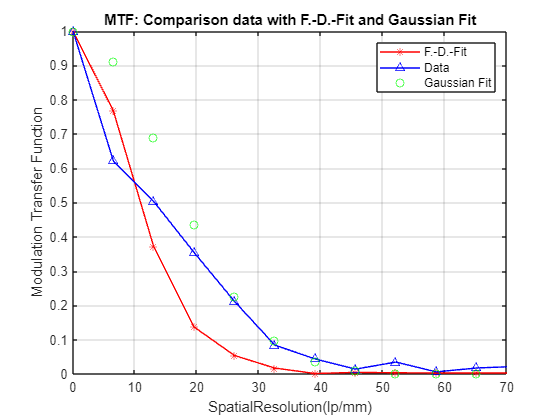



%Now for comparison

plot(sf*h_gffitMTF,hl_fdfitMTF,'* -r',sf*h_gffitMTF,sel_selMTF,'^ -b',sf*h_gffitMTF,hl_gffitMTF,'o g','MarkerIndices',1:1:length(hl_fdfitMTF));
title('MTF: Comparison data with F.-D.-Fit and Gaussian Fit')
xlabel('SpatialResolution(lp/mm)')
ylabel('Modulation Transfer Function')
legend('F.-D.-Fit','Data','Gaussian Fit')
grid on
axis([0 70 0 1]);

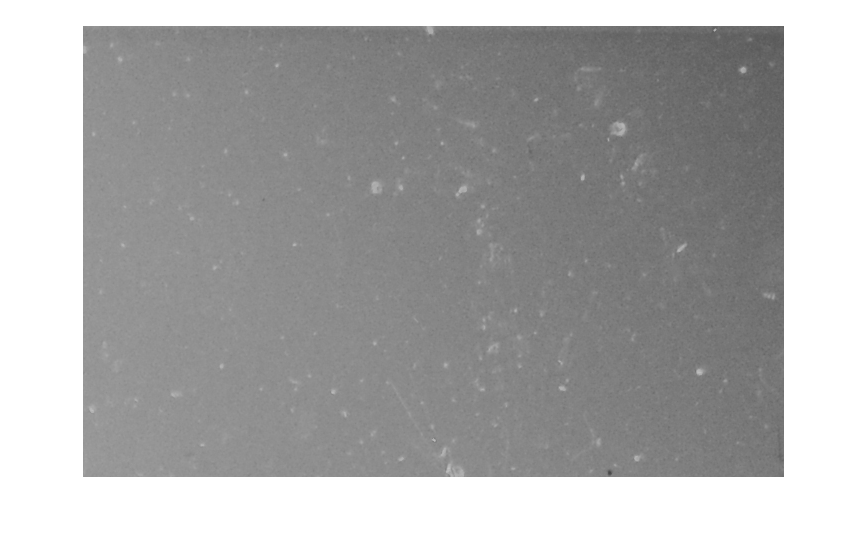





%DETECTIVE QUANTUM EFFICIENCY

%We start of by calculating the Noise Power Spectrum (NPS). The NPS is
%obtained by dividing the image of the scintillating screen at a given dose
%into half overlapping regions of interest (ROIs) of 128x128 pixels. For
%each of these ROIS their pixel fluctuations are then calculated by subtracting the mean
%pixel value. Then, the FFT^2 of each ROI is calculated and in the end, the
%average over all ROIs is taken.

% 1.NOISE POWER SPECTRUM

%Ofcourse, the very first step is to upload the picture and select the
%scintillator


NNPS_image = imread("BA PTPP glass film_200 micron thick.jpg");
% imshow (NNPS_image);
NNPS_image = rgb2gray(NNPS_image);


%Cropped Image must be selected manually 
xs = 2750;
ys = 620;
w = 700;
h = 450;
rect = [xs ys w h];
NNPS_cropped = imcrop(NNPS_image,rect) ;
imshow(NNPS_cropped);


% We then continue by deviding the image into the half overlapping ROIs

[rows, cols, ~] = size(NNPS_cropped);

ans =   Map with properties:

        Count: 398
      KeyType: char
    ValueType: any


ans =   Map with properties:

        Count: 398
      KeyType: char
    ValueType: any


ans =   Map with properties:

        Count: 398
      KeyType: char
    ValueType: any


ans =   Map with properties:

        Count: 398
      KeyType: char
    ValueType: any


ans =   Map with properties:

        Count: 398
      KeyType: char
    ValueType: any


ans =   Map with properties:

        Count: 398
      KeyType: char
    ValueType: any


ans =   Map with properties:

        Count: 398
      KeyType: char
    ValueType: any


ans =   Map with properties:

        Count: 398
      KeyType: char
    ValueType: any


ans =   Map with properties:

        Count: 398
      KeyType: char
    ValueType: any


ans =   Map with properties:

        Count: 398
      KeyType: char
    ValueType: any


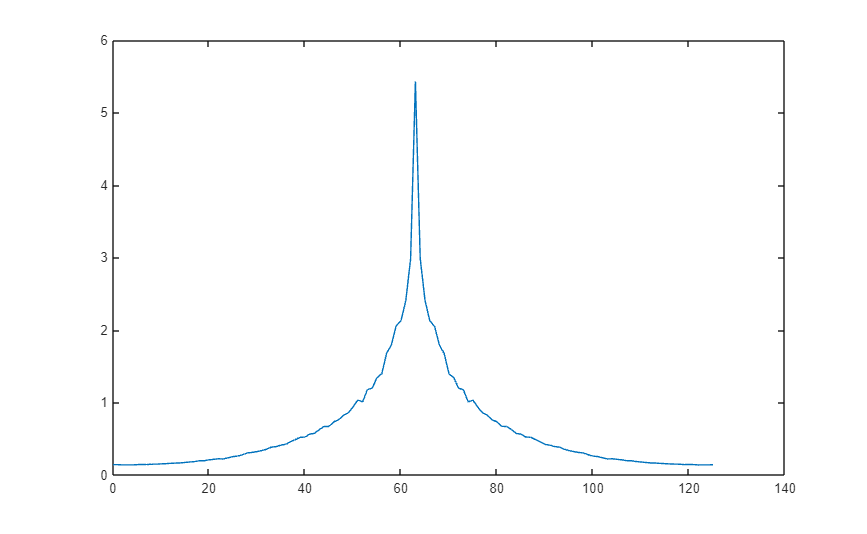


% Define the size of the regions
region_size = 126;

% Calculate the number of rows and columns of regions
num_rows = floor(rows / (region_size./2))-1;
num_cols = floor(cols / (region_size./2))-1;

% Initialize a cell array to store the ROIs
regions = cell(num_rows, num_cols);

% Loop through the image and extract the ROIs
for i = 1:num_rows
    for j = 1:num_cols
        % Calculate the starting and ending row and column indices for each
        % ROI
        start_row = (i - 1) * (region_size./2) + 1;
        end_row = (i+1) * (region_size./2);
        start_col = (j - 1) * (region_size./2) + 1;
        end_col = (j+1) * (region_size./2);
        
        % Extract the region from the image
        region = NNPS_cropped(start_row:end_row, start_col:end_col, :);
        
        % Store the region in the cell array
        regions{i, j} = region;
    end
end

% Display some region
% imshow(regions{4,4});


%Next Step is to use these ROIS for the fft by first caluclating their mean
%value, which I will use instead of the second order 2D Fit. 

% Initialize a cell array to store the regions
means = cell(num_rows, num_cols);

for i = 1:num_rows
    for j = 1:num_cols
        % Go through all ROIs and calculate their mean value pixel value
        M_ROI = regions{i,j} - uint8(mean(mean(regions{i,j})));         
        % Store the region in the cell array
        means{i, j} = M_ROI;
    end
end

%FFT of F
for i = 1:num_rows
    for j = 1:num_cols
        % Go through all ROIs and calculate their mean value pixel value
        fft = fft2(means{i,j});
        fft_shifted = fftshift(fft);
        FFTM_ROI = (abs(fft_shifted))*(abs(fft_shifted));         
        % Store the region in the cell array
        means{i, j} = FFTM_ROI;
    end
end

% Summation of all results
result_sumFFTROI = zeros(size(means{1,1}));

% Loop through the cell array and add each matrix to the result
for i = 1:1:num_rows
    for j = 1:num_cols
        result_sumFFTROI = result_sumFFTROI + means{i,j};
    end
end

%Calculate NPS

M = num_cols+num_rows;
x = region_size;
y = region_size;
dx = 9.6*10^(-3);
dy = dx;
NPS = (dx*dy./(x*y*M))*(result_sumFFTROI);



%Next, we obatin thee 1D NPS by first calculating the 1D NPS in horizontal
%and in veritical direction.

%Horizontal length
shor = size(NPS,2);
%Vertical length
svert = size(NPS,1);
%Now calculate central axes
hzero = shor./2;
vzero = svert./2;

% For the NPS take the average of seven rows or columns on each side of
% the central axes and divide the result by the air-kerma to get the NNPS

% 1. Selection of Horizontal and Vertical ferquency bands, taking 7 in each
% direction

NPShor = NPS([hzero-8:hzero-1 hzero+1:hzero+8],1:end);
NPSvert = NPS(1:end,[vzero-8:vzero-1 vzero+1:vzero+8]);
NPSall = NPS([hzero-8:hzero-1 hzero+1:hzero+8],[vzero-8:vzero-1 vzero+1:vzero+8]);
% 
% imshow(NPSall);
% imshow(NPShor);
% imshow(NPSvert);

%Now taking the average
m_NPShor = mean(NPShor);

%HORIZONTAL DIRECTION

hzerol = length(m_NPShor);
g_NPSh = 0:hzerol-1;
plot(g_NPSh,m_NPShor);

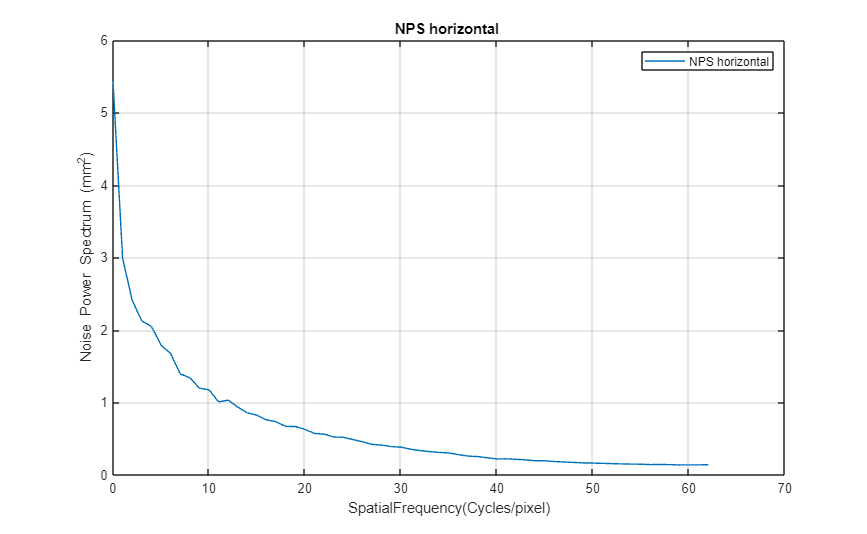


%HALF LENGTH OF HORIZONTAL DIRECTION

m_NPShor = m_NPShor(((hzerol/2)+1):hzerol);
l_NPSh = 0:(hzerol/2)-1 ;
plot(l_NPSh,m_NPShor);
legend('NPS horizontal')
title('NPS horizontal ')
ylabel('Noise Power Spectrum (mm^2)')
xlabel('SpatialFrequency(Cycles/pixel)')
grid on

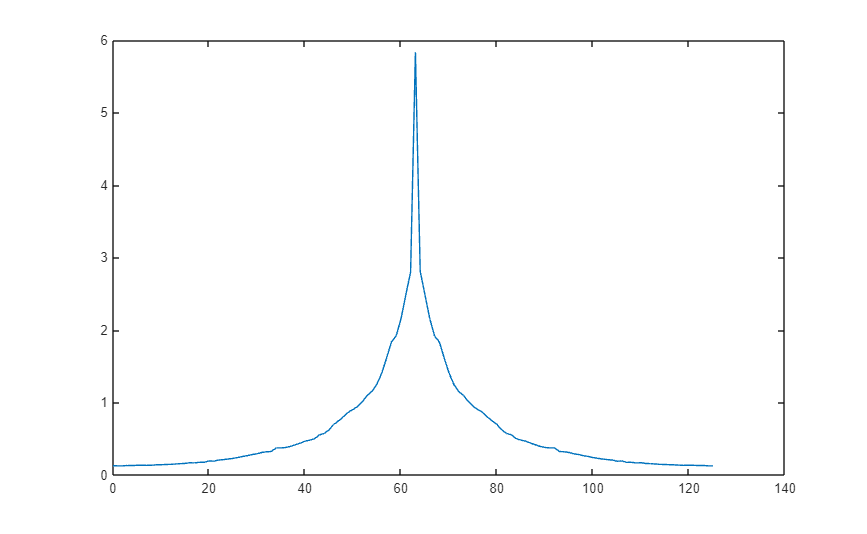


%VERTICAL DIRECTION

m_NPSvert = mean(NPSvert,2);

vzerol =length(m_NPSvert);
g_NPSv = 0:vzerol-1;

%WHOLE LENGTH
plot(g_NPSv,m_NPSvert);

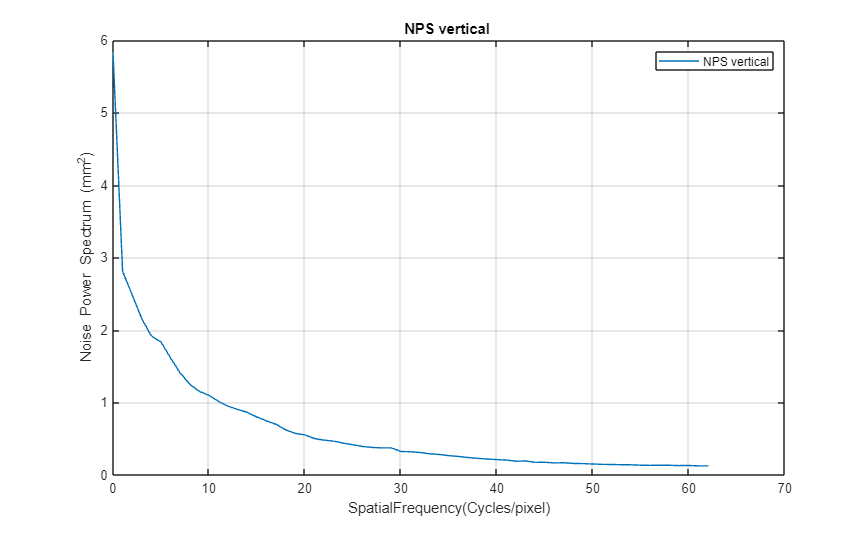


%HALF LENGTH

m_NPSvert = m_NPSvert(((vzerol/2)+1):vzerol);
l_NPSv = 0:(vzerol/2)-1 ;
plot(l_NPSv,m_NPSvert);
legend('NPS vertical')
title('NPS vertical ')
ylabel('Noise Power Spectrum (mm^2)')
xlabel('SpatialFrequency(Cycles/pixel)')
grid on

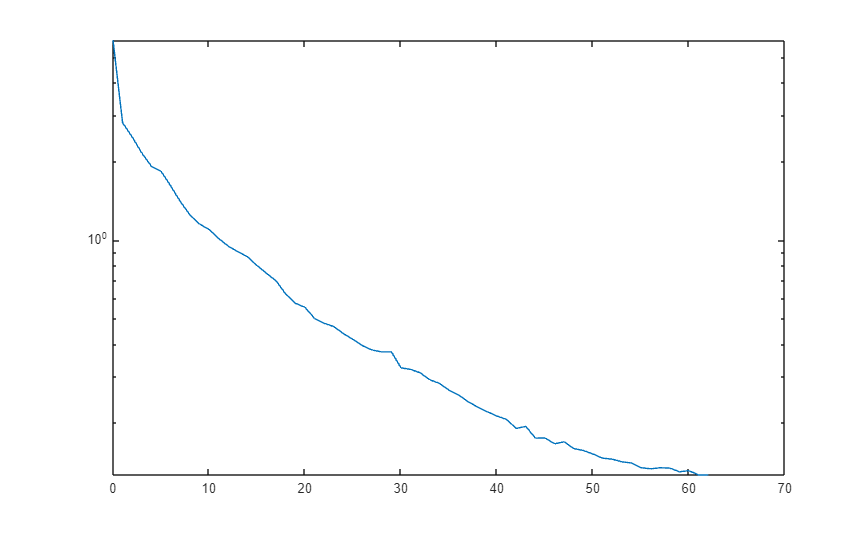

semilogy(l_NPSv,m_NPSvert)

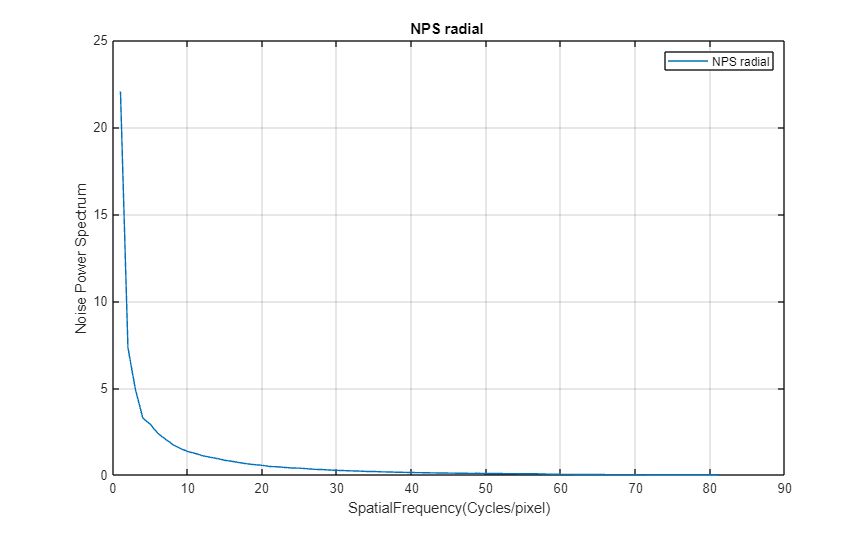



%RADIAL NPS

%For the radial NPS, we selecte the NPS values in radial frequency
%intervalls of [f,f+delta(f)], sum over all these values and divide by the
%number of datapoints used, to obatain the average

% We start of by determining the length of the radial frequency intervall
% and how many frequency steps are in the intervall

v_max = length(l_NPSv);
u_max = length(l_NPSh);

u_0 = 1;
v_0 = 1;

%Set maximum and minimum of radial frequency

f_max = sqrt((u_max.^2)+(v_max.^2));
f_0 = sqrt(2);

% A frequency step is bin = 0.01/pixelpitch
psize = 0.0096;
bin = 0.01/psize;
f = f_0:f_max;

lf = length(f)-1; %Länge des Intervall, dass f abdeckt

% Number of steps, take and substract the modulus to get a naturel number

modbin = mod(lf,bin);
%Number of frequency steps i
ni = ((lf-modbin)./bin);
%Define cell arrays to save the results
NPSf = cell(1, ni);
tNPSF = cell(1,ni);
for col = 1:ni
      NPSf{1,col} = 0;
end
for u = 1:u_max;
   for v = 1:v_max;
       uv = sqrt((u.^2)+(v.^2));
       uvcell{u,v} =uv;
   end
end
%Now check intervals [f+(i-1)*deltaf;f+(i*deltaf)] for the NPS values and
%calculate average of them.
for i = 1:ni
    %Running variable to note number of values in the interval

    l = 0;
    for u = 1:u_max-3
        for v = 1:v_max-3
            if uvcell{u,v} >= (1+(i-1)*bin) && uvcell{u,v} <= (1+(i)*bin) 
             l = l+1;   
             sumresult = sum(NPS(hzero+u,vzero+v));
             NPSf{1,i} = NPSf{1,i}+sumresult;

            end
        end
    end
    tNPSF{1,i} = (1./l)*NPSf{1,i};
end

%Finally, display the result
coll = 1:ni;
plot(coll, [tNPSF{1,coll}]);
legend('NPS radial')
title('NPS radial ')
ylabel('Noise Power Spectrum ')
xlabel('SpatialFrequency(Cycles/pixel)')
grid on

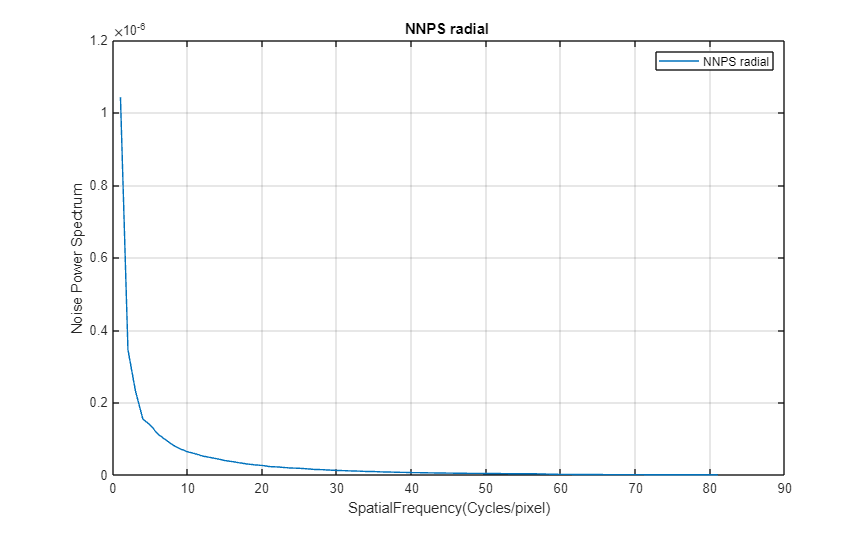

%Now display the other results to compare the and alos display them in
%their order


m_NPSvert = m_NPSvert';

% Plot vertical and horizontal against one another
dose = 4.6*10^3;
m_NNPShor = m_NPShor./(dose^2);
m_NNPSvert = m_NPSvert./(dose^2);

coll = 1:ni;
plot(coll, [tNPSF{1,coll}]/(dose^2));
legend('NNPS radial')
title('NNPS radial ')
ylabel('Noise Power Spectrum ')
xlabel('SpatialFrequency(Cycles/pixel)')
grid on

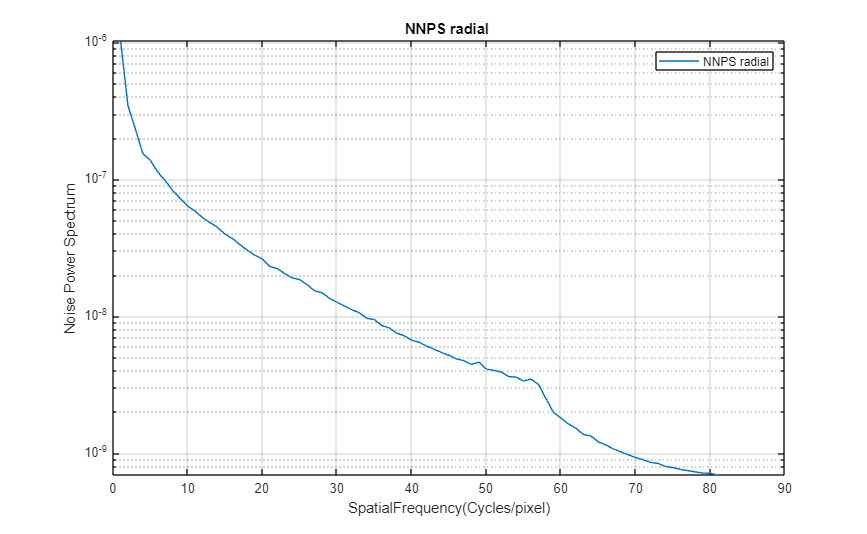


semilogy(coll, [tNPSF{1,coll}]/(dose^2));
legend('NNPS radial')
title('NNPS radial ')
ylabel('Noise Power Spectrum ')
xlabel('SpatialFrequency(Cycles/pixel)')
grid on

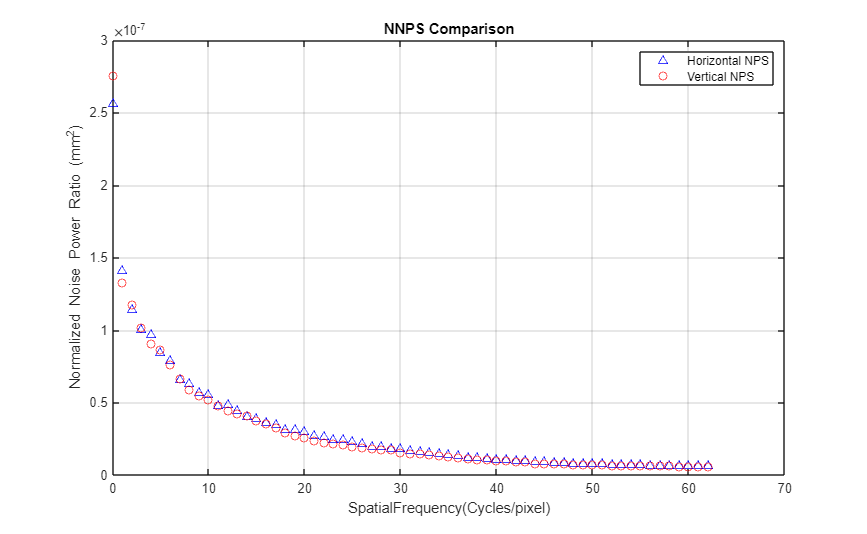


plot(l_NPSh,m_NNPShor,'b ^',l_NPSv,m_NNPSvert,'r o');
legend('Horizontal NPS', 'Vertical NPS')
title('NNPS Comparison')
ylabel('Normalized Noise Power Ratio (mm^2)')
xlabel('SpatialFrequency(Cycles/pixel)');
grid on

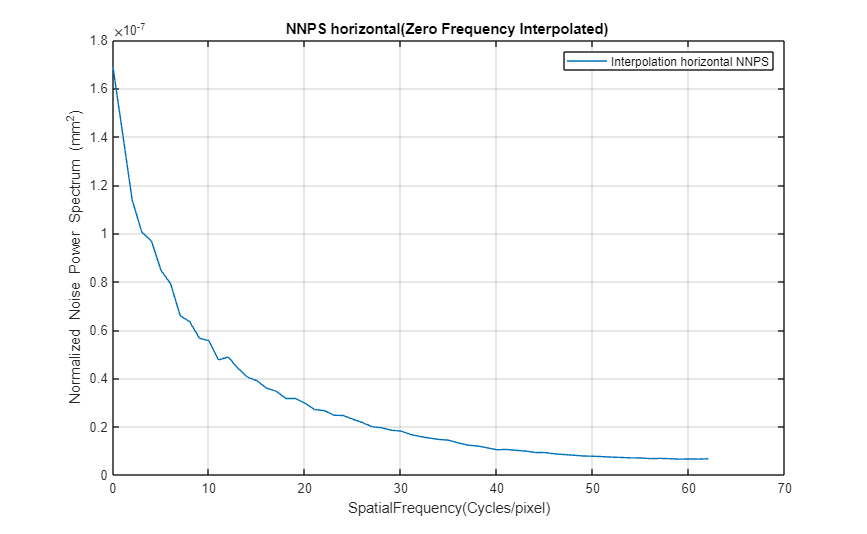



%%%%% Extrapolation for zero NNPS values



M_NNPScor = m_NNPShor;
dfn = m_NNPShor(2)-m_NNPShor(3);
M_NNPScor(1) = m_NNPShor(2)+dfn;
plot(l_NPSh,M_NNPScor);

legend('Interpolation horizontal NNPS')
title('NNPS horizontal(Zero Frequency Interpolated) ')
ylabel('Normalized Noise Power Spectrum (mm^2)')
xlabel('SpatialFrequency(Cycles/pixel)')
grid on

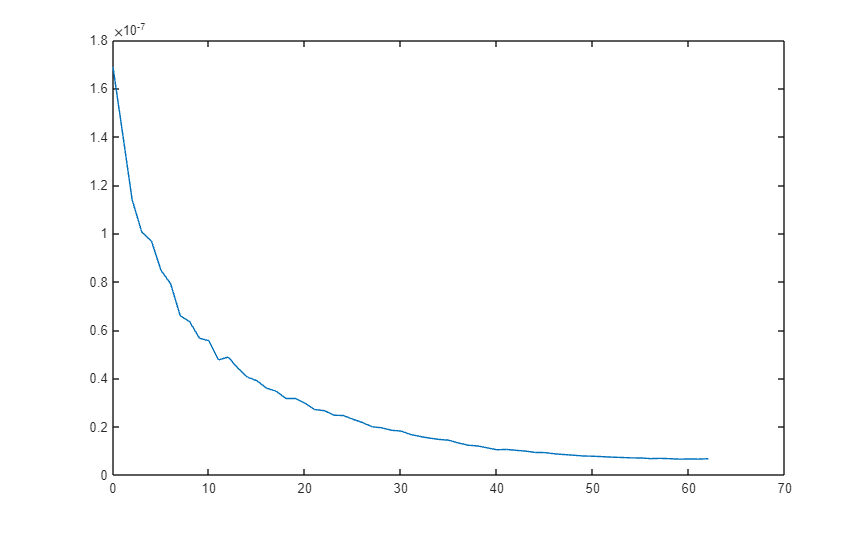


M_NNPScorv = m_NNPSvert;
dfnv = m_NNPSvert(2)-m_NNPSvert(3);
M_NNPScor(1) = m_NNPShor(2)+dfn;
plot(l_NPSh,M_NNPScor);

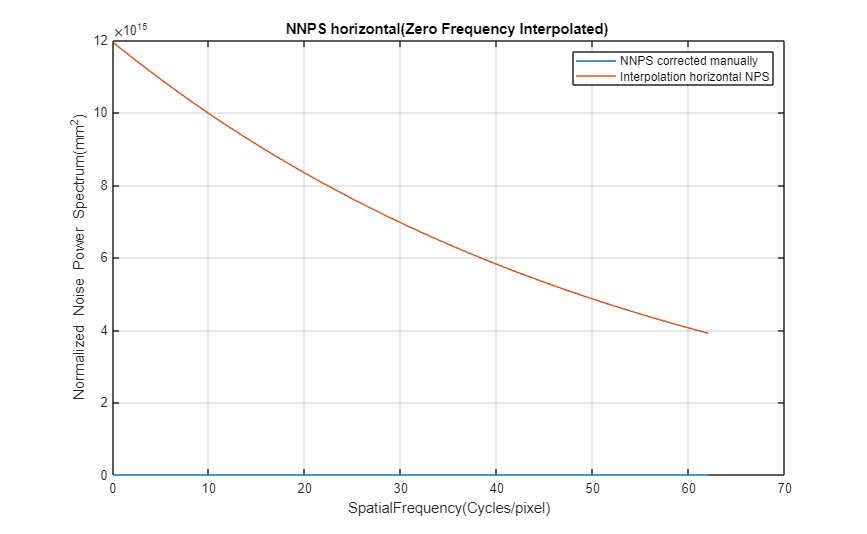




%%%% Interpolation
x = l_NPSh;
a = 1.1936e+16;
b = -0.0180;
estra = a*exp(b*x);
plot(l_NPSh,M_NNPScor,l_NPSh,estra);
legend('NNPS corrected manually','Interpolation horizontal NPS')
title('NNPS horizontal(Zero Frequency Interpolated) ')
ylabel('Normalized Noise Power Spectrum(mm^2)')
xlabel('SpatialFrequency(Cycles/pixel)')
grid on


semilogy(l_NPSh,M_NNPScor);
legend('NNPS corrected manually','Interpolation horizontal NPS')

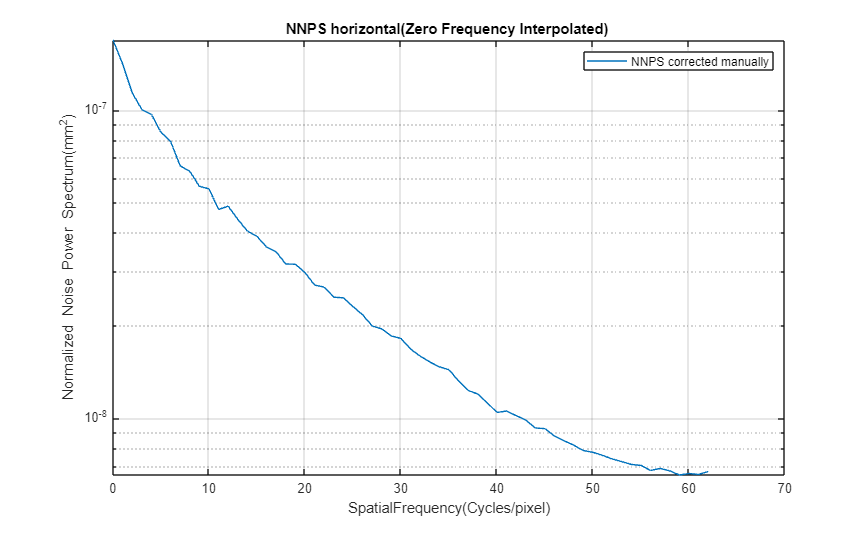

title('NNPS horizontal(Zero Frequency Interpolated) ')
ylabel('Normalized Noise Power Spectrum(mm^2)')
xlabel('SpatialFrequency(Cycles/pixel)')
grid on

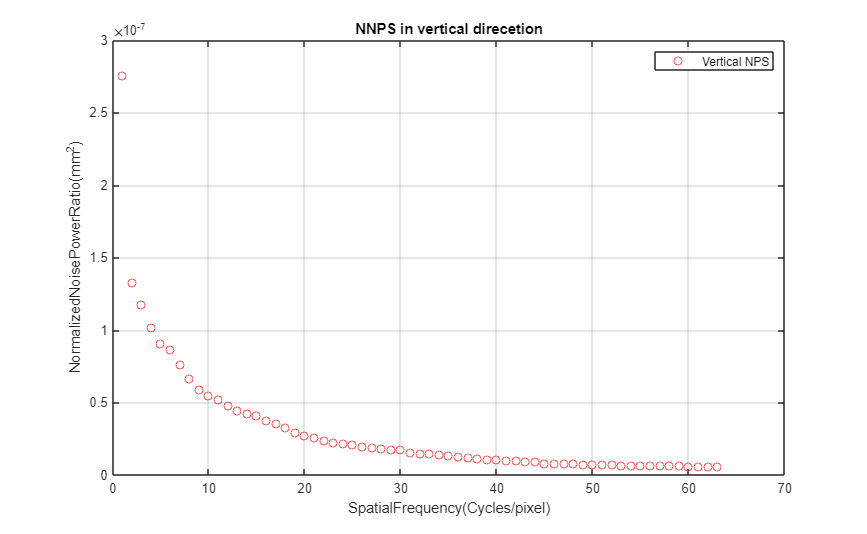





%Plot the Vertical Direction indiviually
plot(m_NNPSvert,'o','Color','r');
legend('Vertical NPS')
title('NNPS in vertical direcetion')
ylabel('NormalizedNoisePowerRatio(mm^2)')
xlabel('SpatialFrequency(Cycles/pixel)')
grid on


h = 1:64

h =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


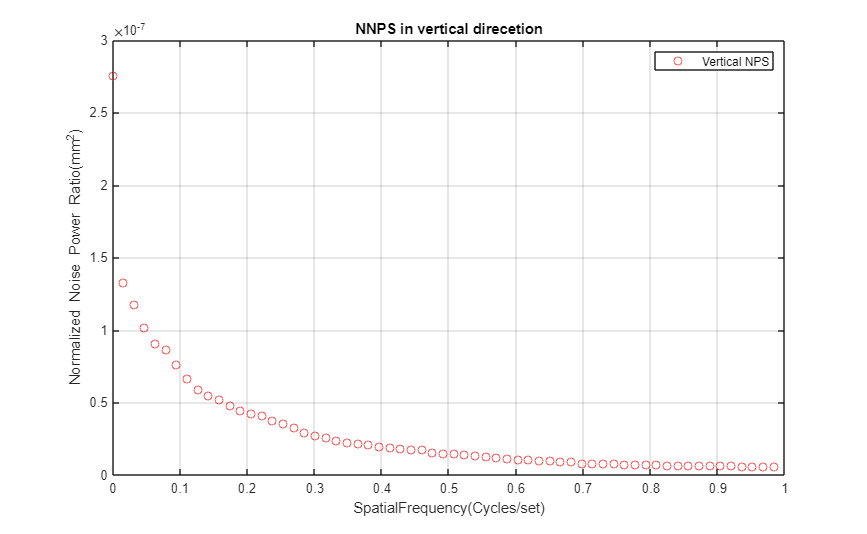


%CONVERSION TO CYCLES/SET
set = 1/(length(m_NNPSvert));

plot(l_NPSv*set,m_NNPSvert,'o','Color','r');
legend('Vertical NPS')
title('NNPS in vertical direcetion')
ylabel('Normalized Noise Power Ratio(mm^2)')
xlabel('SpatialFrequency(Cycles/set)')
grid on

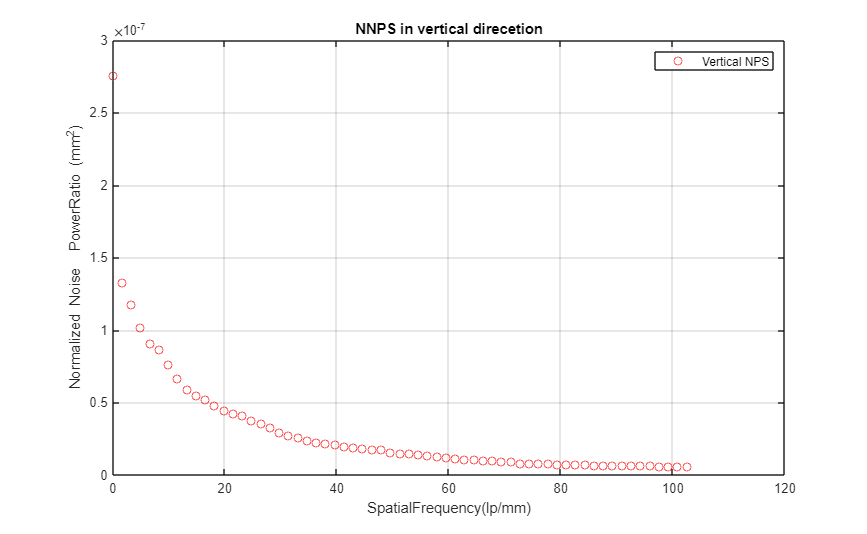


%%% LINEPAIR PER MM

pp = 0.0096;                        %pixelpitch in mm
set = set*(1/pp);

plot(l_NPSv*set,m_NNPSvert,'o','Color','r');
legend('Vertical NPS')
title('NNPS in vertical direcetion')
ylabel('Normalized Noise  PowerRatio (mm^2)')
xlabel('SpatialFrequency(lp/mm)')
grid on

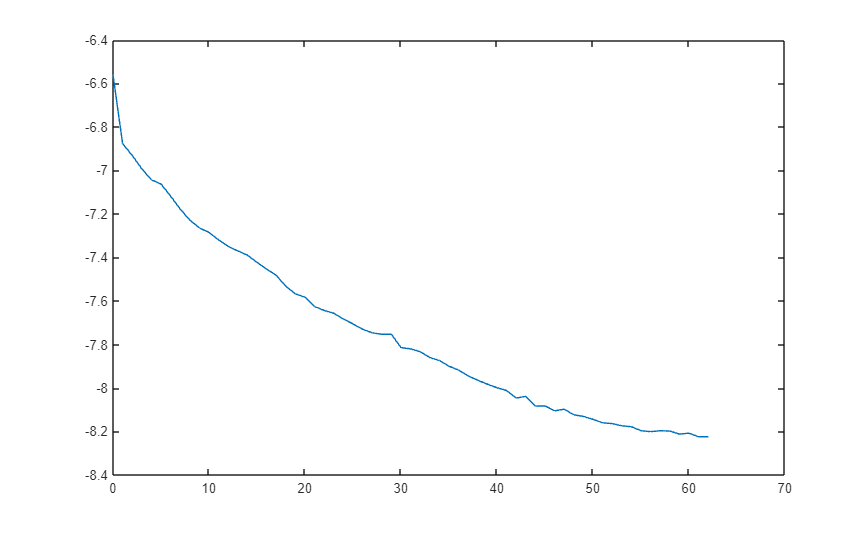




%%%DETECTIVE QUANTUM EFFICIENCY

%For the DQE, divide MTF^2 by Normalized Noise Power Spectrum (NNPS) times the average x-ray input fluence per image aquisition. 

% dose= 4.*10.^-3; %Just so that I have it predefined
% dose = 4.*10.^-6;

o = 0:(region_size/2)-1;
q = 2.3.*10^3;

% Plor the vertical NPS again
m_NNPSvert = m_NNPSvert(1:(region_size/2));
% m_NPSvert = m_NPSvert:/max(m_NPSvert);
plot(o,log10(m_NNPSvert))

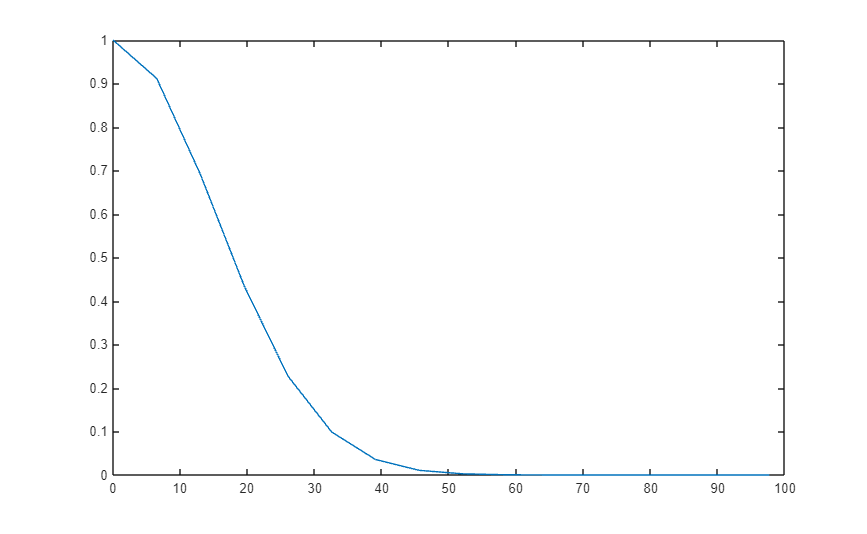

fo = 0:length(hl_gffitMTF)-1;
lps = 1/length(fo);
lps = lps*(1/psize);


%Calulate and plot the NNPS

% m_NNPSvert = m_NPSvert*(1/(dose^2));
% plot(o,log10(m_NPSvert));

%Calculate and plot MTF^2

% hldqe_gffitMTF= hl_gffitMTF(1:(region_size/2));
hldqe_gffitMTF= hl_gffitMTF;
plot(fo*lps,hldqe_gffitMTF);

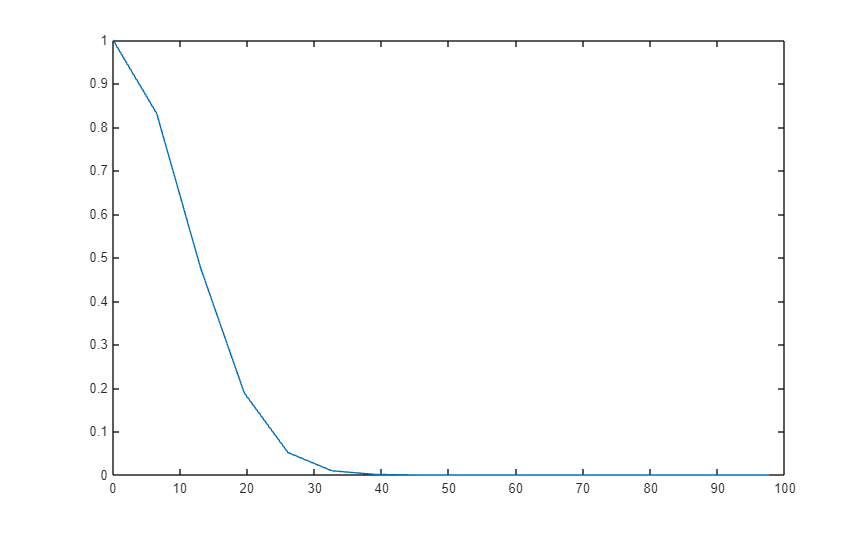

hldqe_gffitMTF = (hldqe_gffitMTF).*(hldqe_gffitMTF);

plot(fo*lps,hldqe_gffitMTF)

oo = 1:85

oo =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


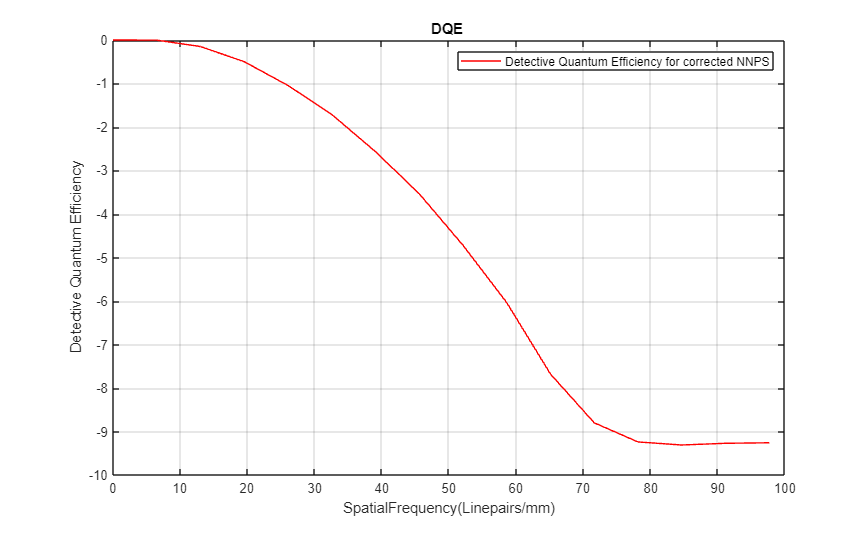

% dqe2 = hl_gffitMTF(1:85)
% plot(oo,hl_gffitMTF./[tNPSF{1,oo}]);

%Plot DQE on log scale 
% M_NNPScor = M_NNPScor(1:(region_size/2));
M_NNPScor = M_NNPScor(1:length(hldqe_gffitMTF));
beef = hldqe_gffitMTF./M_NNPScor;
% beef = beef.*(1./(q*dose));
beef = beef./max(beef);

plot(fo*lps,log10(beef),'r');
legend('Detective Quantum Efficiency for corrected NNPS')
title('DQE ')
ylabel('Detective Quantum Efficiency')
xlabel('SpatialFrequency(Linepairs/mm)')
grid on

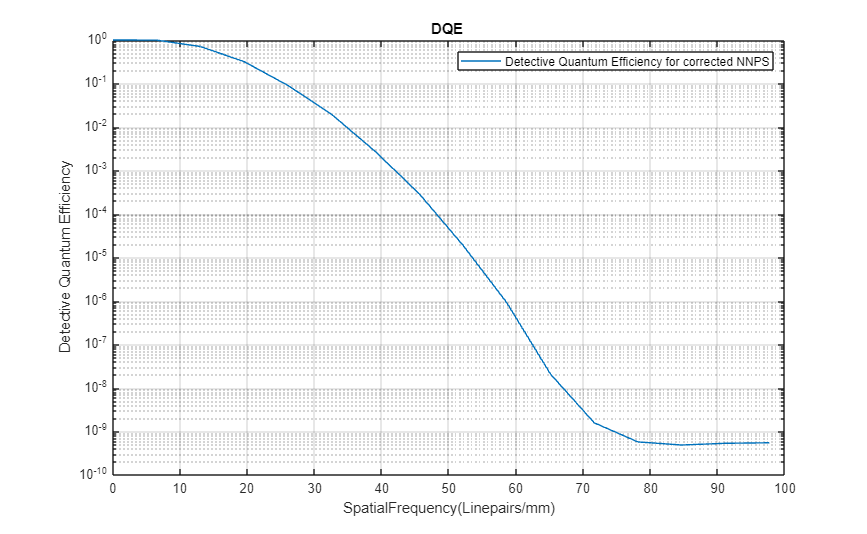



semilogy(fo*lps,beef);
legend('Detective Quantum Efficiency for corrected NNPS')
title('DQE ')
ylabel('Detective Quantum Efficiency')
xlabel('SpatialFrequency(Linepairs/mm)')
grid on

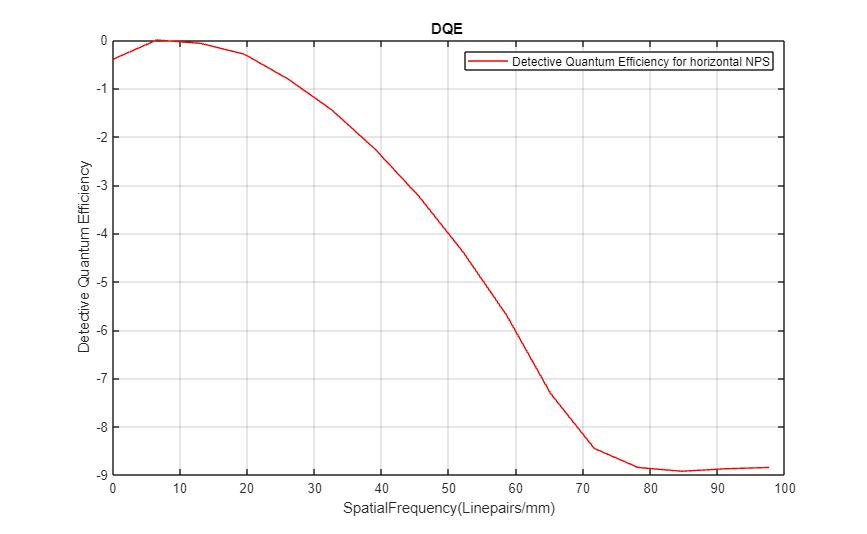


estra = estra(1:length(hldqe_gffitMTF));
beefest = q*hldqe_gffitMTF./[tNPSF{1,fo+1}];
% beef = beef.*(1./(q*dose));
beefest = beefest./max(beefest);

plot(fo*lps,log10(beefest),'r');
legend('Detective Quantum Efficiency for horizontal NPS')
title('DQE ')
ylabel('Detective Quantum Efficiency')
xlabel('SpatialFrequency(Linepairs/mm)')
grid on

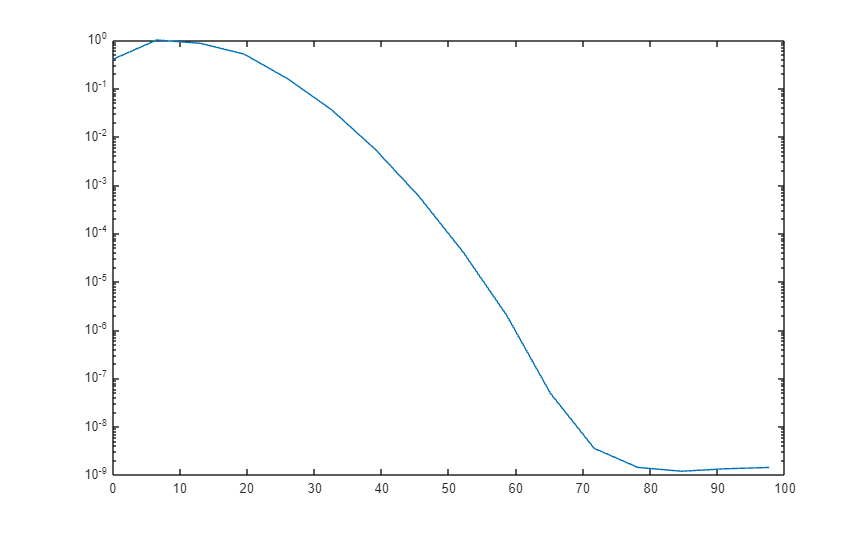

semilogy(fo*lps,beefest);